% 专用车道情况对比
clear; clc; close all;
%
%-----------------------------
% 1. 关于theta
%——---------------------------
D = 4000; % 需求规模
s = 2000;

alpha1 = 6.4;         
beta = 0.61*alpha1;
gamma = 2.38*alpha1;

n = 6;
Cb = 20;
Cab = Cb/n; % 平均公交成本
Ct = beta*gamma/(beta+gamma)*D/s;        % 全私家车通勤成本

lambda = 4;        % 模块化公交效率参数
R_Nm_star = 500;      % 固定收益（R(N_m^*)）


%-------------------------------
% 专用道系数
%-------------------------------
theta = linspace(0.01, 0.89, 500);  % 必须小于 alpha1


Nm = theta .* lambda/(1-theta+theta .* lambda)*D/(2*n)*(1-(1-theta) .* (Cab/Ct))

Nm =   128.2248  128.4834  128.7420  129.0006  129.2591  129.5177  129.7763  130.0349  130.2934  130.5520  130.8106  131.0692  131.3277  131.5863  131.8449  132.1034  132.3620  132.6206  132.8792  133.1377  133.3963  133.6549  133.9135  134.1720  134.4306  134.6892  134.9478  135.2063  135.4649  135.7235  135.9821  136.2406  136.4992  136.7578  137.0164  137.2749  137.5335  137.7921  138.0507  138.3092  138.5678  138.8264  139.0849  139.3435  139.6021  139.8607  140.1192  140.3778  140.6364  140.8950


p = 1/2 * ((1 ./ (1-theta)) .* Ct+Cab)

p =     4.8056    4.8112    4.8168    4.8225    4.8281    4.8338    4.8395    4.8452    4.8510    4.8567    4.8625    4.8683    4.8742    4.8800    4.8859    4.8918    4.8977    4.9036    4.9096    4.9155    4.9215    4.9276    4.9336    4.9397    4.9458    4.9519    4.9580    4.9642    4.9704    4.9766    4.9828    4.9891    4.9953    5.0016    5.0080    5.0143    5.0207    5.0271    5.0335    5.0399    5.0464    5.0529    5.0594    5.0660    5.0725    5.0791    5.0858    5.0924    5.0991    5.1058



C = 1/2 * Ct .* (1 ./ (1-theta+theta .* lambda) +...
    1 ./ (1-theta)) + 1/2 .* (theta .* lambda)./(1-theta+theta .* lambda) * Cab

C =     6.2207    6.2219    6.2231    6.2245    6.2259    6.2274    6.2289    6.2305    6.2321    6.2338    6.2356    6.2374    6.2393    6.2413    6.2433    6.2454    6.2475    6.2497    6.2519    6.2542    6.2566    6.2590    6.2614    6.2640    6.2665    6.2692    6.2718    6.2746    6.2774    6.2802    6.2831    6.2861    6.2891    6.2921    6.2952    6.2984    6.3016    6.3049    6.3082    6.3116    6.3150    6.3185    6.3220    6.3255    6.3292    6.3328    6.3366    6.3403    6.3442    6.3480


Pi = n .*Nm .*p + R_Nm_star - Nm .*Cab

Pi = 1.0e+04 *

    0.3770    0.3781    0.3792    0.3803    0.3814    0.3825    0.3836    0.3847    0.3858    0.3869    0.3880    0.3892    0.3903    0.3914    0.3926    0.3937    0.3948    0.3960    0.3971    0.3983    0.3994    0.4006    0.4018    0.4029    0.4041    0.4053    0.4065    0.4076    0.4088    0.4100    0.4112    0.4124    0.4136    0.4148    0.4160    0.4172    0.4185    0.4197    0.4209    0.4221    0.4234    0.4246    0.4259    0.4271    0.4283    0.4296    0.4309    0.4321    0.4334    0.4347


CS = 1/2*1 ./(1-theta)*Ct*n .*Nm

CS = 1.0e+04 *

    0.2415    0.2424    0.2433    0.2443    0.2452    0.2461    0.2471    0.2480    0.2489    0.2499    0.2508    0.2518    0.2527    0.2537    0.2547    0.2556    0.2566    0.2576    0.2585    0.2595    0.2605    0.2615    0.2625    0.2635    0.2645    0.2655    0.2665    0.2675    0.2685    0.2695    0.2706    0.2716    0.2726    0.2736    0.2747    0.2757    0.2768    0.2778    0.2789    0.2799    0.2810    0.2821    0.2831    0.2842    0.2853    0.2864    0.2874    0.2885    0.2896    0.2907


SW = CS + Pi

SW = 1.0e+04 *

    0.6185    0.6205    0.6225    0.6245    0.6265    0.6286    0.6306    0.6327    0.6347    0.6368    0.6389    0.6409    0.6430    0.6451    0.6472    0.6493    0.6514    0.6536    0.6557    0.6578    0.6600    0.6621    0.6643    0.6664    0.6686    0.6708    0.6730    0.6752    0.6774    0.6796    0.6818    0.6840    0.6862    0.6885    0.6907    0.6930    0.6952    0.6975    0.6998    0.7021    0.7044    0.7067    0.7090    0.7113    0.7136    0.7160    0.7183    0.7207    0.7230    0.7254


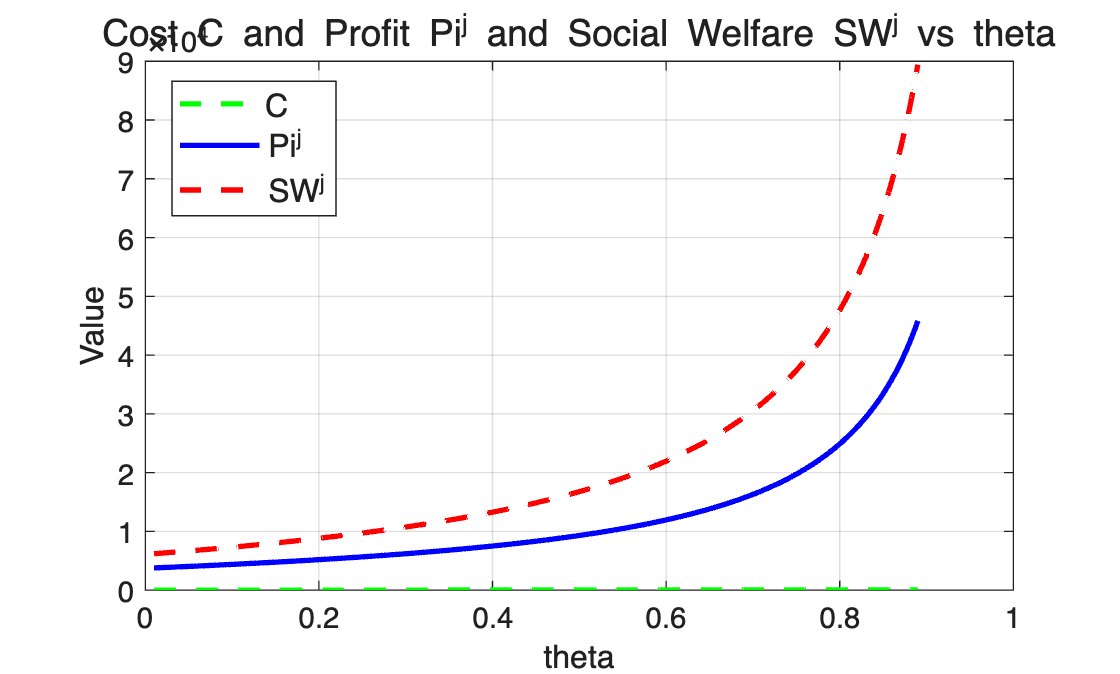



%-------------------------------
% 绘图
%-------------------------------
figure;
plot(theta, C, 'g--','LineWidth', 2); hold on;
plot(theta, Pi, 'b-', 'LineWidth', 2); hold on;
plot(theta, SW, 'r--', 'LineWidth', 2);

xlabel('theta', 'FontSize', 12);
ylabel('Value', 'FontSize', 12);
title('Cost C and Profit Pi^j and Social Welfare SW^j vs theta', 'FontSize', 14);
legend({'C', 'Pi^j', 'SW^j'}, 'FontSize', 12, 'Location', 'best');

grid on; box on;

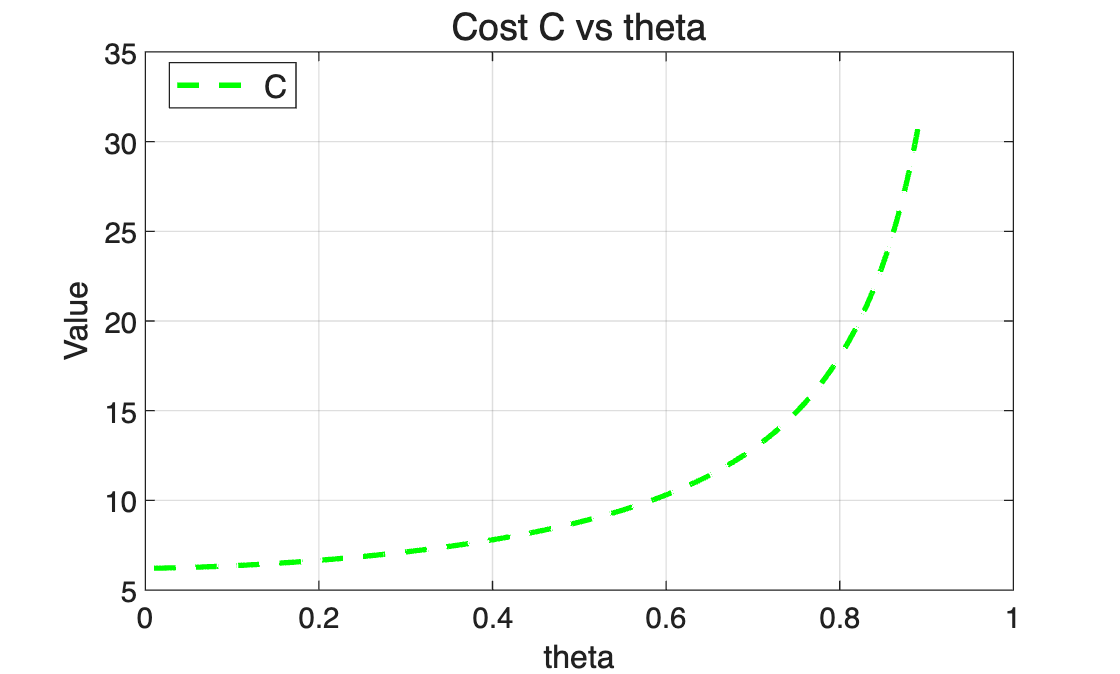


%
figure;
plot(theta, C, 'g--','LineWidth', 2); hold on;

xlabel('theta', 'FontSize', 12);
ylabel('Value', 'FontSize', 12);
title('Cost C vs theta', 'FontSize', 14);
legend({'C'}, 'FontSize', 12, 'Location', 'best');

grid on; box on;







%{
clear; clc; close all;

%-----------------------------
% 2. 关于 lambda
%-----------------------------
D = 4000; % 需求规模
s = 2000;

alpha1 = 6.4;
beta = 0.61 * alpha1;
gamma = 2.38 * alpha1;

n = 6;
Cb = 20;
Cab = Cb / n; % 平均公交成本
Ct = beta * gamma / (beta + gamma) * D / s; % 全私家车通勤成本

theta = 0.3;
R_Nm_star = 500; % 固定收益

%-------------------------------
% 自动驾驶水平
%-------------------------------
lambda = linspace(1.0, 9.9, 500)

Nm = theta .* lambda ./ (1 - theta + theta .* lambda) * D / (2 * n) ...
     .* (1 - (1 - theta) * (Cab / Ct))

p = 0.5 * ((1 / (1 - theta)) * Ct + Cab)

Pi = n .* Nm .* p + R_Nm_star - Nm .* Cab
CS = 0.5 * (1 ./ (1 - theta)) .* Ct .* n .* Nm
SW = CS + Pi

%-------------------------------
% 绘图
%-------------------------------
figure;
plot(lambda, Pi, 'b-', 'LineWidth', 2); hold on;
plot(lambda, SW, 'r--', 'LineWidth', 2);

xlabel('$\lambda$', 'Interpreter','latex', 'FontSize', 12);
ylabel('Value', 'FontSize', 12);
title('Profit $\Pi^j$ and Social Welfare $SW^j$ vs $\lambda$', ...
      'Interpreter','latex', 'FontSize', 14);
legend({'$\Pi^j$', '$SW^j$'}, 'Interpreter','latex', ...
       'FontSize', 12, 'Location', 'best');

grid on; box on;

%}

